# Signal after MAX2771

%rawdata = randi([0 1], [1 50e3]); 
rawdata = [1 0 1 1 0 1];
%rawdata = [1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1];

%fd      = 50;               % Data frequency
%fca     = 1.023e6;          % C/A code frequency
fd      = 5;               % Data frequency
fca     = 1.023e5;          % C/A code frequency
fc      = fca*20;        % Carrier frequency (Adjusted to not overload RAM)
%fc      = 1575.42e6;        % Carrier frequency
fs      = 10*fc;
sv_id   = 1;                % Satellite Vehicle ID
n       = 1;                % BPSK(1) fc = n*1.023e6; %code rate BPSK(n) spreading code rate n*1.023 MHz
codeLength = round(1023/n); 

fdoppler = [80, 300, -200,0];

Rsignal = (.2*Received(rawdata,fd,fca,fc,fs,fdoppler(1),1,1,0) + ...
          .2*Received(rawdata,fd,fca,fc,fs,fdoppler(2),8,1,30) + ...
          .2*Received(rawdata,fd,fca,fc,fs,fdoppler(3),20,1,834) + ...
          .2*Received(rawdata,fd,fca,fc,fs,fdoppler(4),12,1,514) + ...
          .2*Received(rawdata,fd,fca,fc,fs,-400,28,1,230));

[I,Q, clk] = MAX2771(Rsignal, fc, fs, fs/(20*fca*fd), true);
[In,Qn, clk] = MAX2771(awgn(Rsignal,-20), fc, fs, fs/(20*fca*fd), true);

## Acquisition search

% Search Parameters
fdoppler_step = 100;
doppler_search = 1e3;
w_search = -doppler_search/2:fdoppler_step:doppler_search/2;

% take n miliseconds
nms = 1;
Acquisition_len = nms*(clk/(fd*20));
%Result = Acquisition(I,Q,Acquisition_len,codeLength,nms,doppler_search,fdoppler_step,clk);

I_acquisition = I(1:Acquisition_len);
Q_acquisition = Q(1:Acquisition_len);
IQ = I_acquisition + 1i*Q_acquisition;

%[Max_Corr,index] = Acquisition_search(codeLength,nms,doppler_search,fdoppler_step,clk,IQ);

for SV = 1:32
    % Generate gold code
    gc = data_mapper(gold_code_L1(codeLength,SV));
    gc = upsampler(gc,4);
    gc = expand(gc,nms);
    
    w = 1;
    for w_doppler = -doppler_search/2:fdoppler_step:doppler_search/2
        doppler_wave = exp(1i*2*pi*w_doppler*(0:length(IQ)-1)/(clk*nms)); % O misturador deve ser complexo de forma a eliminar o efeito doppler
        IQ_fft = fft(downsampler(IQ.*doppler_wave,25,5));
        GC = fft(gc);
        [Max_Corr(SV,w), index(SV,w)] = max(abs(ifft(IQ_fft.*conj(GC))).^2);
        w = w + 1;
    end
end
[sv, wd] = find(Max_Corr > 1e6);
W_ = -doppler_search/2 + fdoppler_step*(wd-1);
chips = 0;
for n = 1:length(sv)
    chips(n) = round(index(sv(n),wd(n))/4);
end

Result = sortrows([sv,W_,chips']); %Fim da aquisição

I_acquisitionn = In(1:Acquisition_len);
Q_acquisitionn = Qn(1:Acquisition_len);
IQn = I_acquisitionn + 1i*Q_acquisitionn;


%[Max_Corr,index] = Acquisition_search(codeLength,nms,doppler_search,fdoppler_step,clk,IQ);

for SV = 1:32
    % Generate gold code
    gc = data_mapper(gold_code_L1(codeLength,SV));
    gc = upsampler(gc,4);
    gc = expand(gc,nms);
    
    wn = 1;
    for w_doppler = -doppler_search/2:fdoppler_step:doppler_search/2
        doppler_wave = exp(1i*2*pi*w_doppler*(0:length(IQn)-1)/(clk*nms)); % O misturador deve ser complexo de forma a eliminar o efeito doppler
        IQ_fftn = fft(downsampler(IQn.*doppler_wave,25,5));
        GC = fft(gc);
        Correlation(SV,wn,:) = abs(ifft(IQ_fftn.*conj(GC))).^2;
        [Max_Corrn(SV,wn), indexn(SV,wn)] = max(Correlation(SV,wn,:));
        wn = wn + 1;
    end
end

[svn, wdn] = find((Max_Corrn > 1e6) == 1);
W_n = -doppler_search/2 + fdoppler_step*(wdn-1);
chipsn = 0;
for n = 1:length(svn)
    chipsn(n) = round(indexn(svn(n),wdn(n))/4);
end

Resultn = sortrows([svn,W_n,chipsn']); %Fim da aquisição

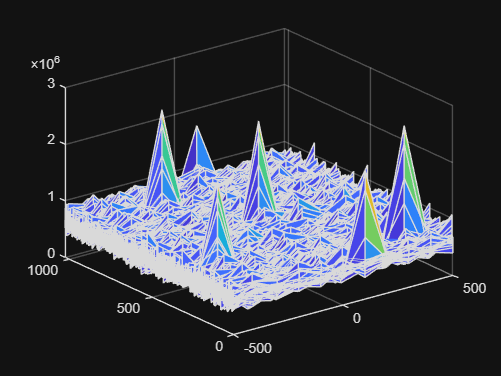

Plot_result = reshape(sum(Correlation,1), [11 size(GC,2)]);
chip_data = ones(11,1).*[0:1/4/nms:1023-1/4/nms];
w_plot = ones(size(GC)).*w_search';

surf(w_plot,chip_data,Plot_result);